#### Linear advection simulation using FTBS scheme and calculating numerical amplification factor

One-Dimesional linear convection equation is:


$$\frac{\partial u}{\partial t}+c\frac{\partial u}{\partial x}=0$$


Discretizng using forward in time and backward in space gives


$$u^{n+1}=u^n-\frac{c\Delta t}{h}(u^n_{i}-u^n_{i-1})$$


Converting the above equation in the spectral plane, we get


$$	\tilde{U}^{n+1}=\tilde{U}^{n} - CFL \left(\tilde{U}^{n}-\tilde{U}^{n} \exp(-ikh)\right),$$


Numerical amplification factor is:


$$G_{FTBS} = 1 -CFL (1-\exp (-ikh))$$


clc
clear all
close all
format long

Domain Length is 2 $\pi$ and divided into 101 points. Initial condtion used is sin(x) with wave number 1.

l=2*pi;
n=101;
k=1;
x=linspace(0,l,n);
y=sin(k*x);

Delete the last point to avoid repetion, because $y(2\pi)=y(0)$

x(end)=[];
y(end)=[];
dx=l/(n-1);

Flow time is 5 s and calculate $\Delta t$ from CFL number

T=5;
c=1;
cfl=0.5;
dt=cfl/c*dx;
nt=round(T/dt);

Solving PDE

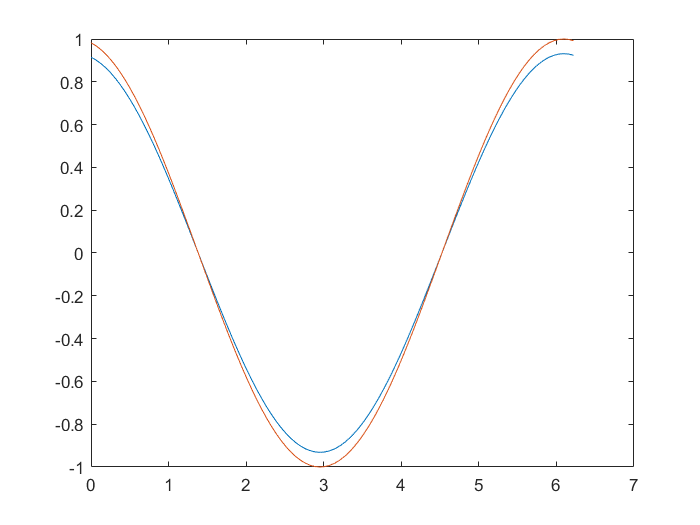

qw1=round(nt/10); % plot number of framed

for i =1:nt
    y0=y;

        dy=PerDerivative_L1R0(y,dx); % derivative calculating function
        yn=y0-1/1*c*dt*dy; %FTBS implmetation
        t1=dt*(i);
        yex=sin(k*(x-c*t1)) ; % exact solution

        y=yn;

if mod(i,qw1)==0
    plot(x,yn,x,yex)
    drawnow
end
Fs=1/dx;
Ts=dx;
[YfreqD,freqRng] = positiveFFT(y,Fs,yex);%FFT calculating function
fft_mag(i)=max((YfreqD)); % storing dominent frequncy
end

Numerical amplification factor is:

gsim=mean(fft_mag(2:end)./fft_mag(1:end-1));
fprintf('Numerical amplification factor from simulation =\n %f%+fj\n',real(gsim),imag(gsim));

Numerical amplification factor from simulation =
 0.999013-0.031395j


Theoritical amplification factor

kh=dx*k;
G_ex=1-cfl*(1-exp(-1i*kh)); % Theoritical Numerical gain of FTBS
G_mag=((G_ex));
fprintf('Numerical amplification factor from theory =\n %f%+fj\n',real(G_ex),imag(G_ex));

Numerical amplification factor from theory =
 0.999013-0.031395j


Plotting the frequncy 

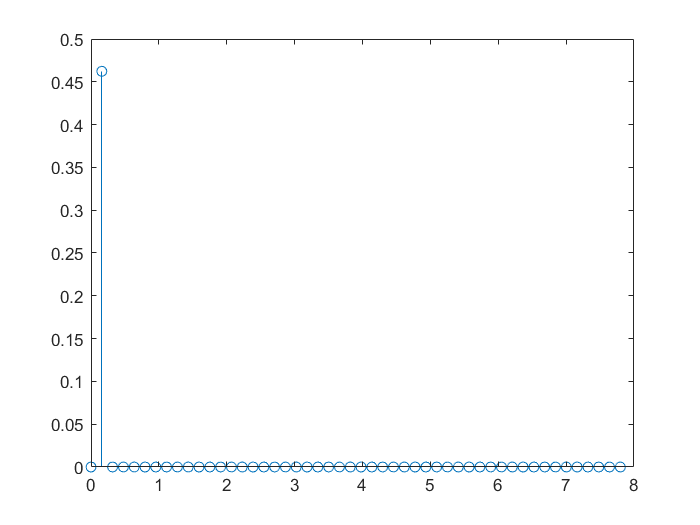

stem(freqRng,abs(YfreqD));

[M,I] = max(abs(YfreqD));
fprintf('Frequency of the FFT signal is %f', freqRng(I))

Frequency of the FFT signal is 0.159155

fprintf('Frequency of the input signal is %f', k/2/pi)

Frequency of the input signal is 0.159155